% process data
filename = "CrossStep\crossstep1.mat"

filename = "CrossStep\crossstep1.mat"

[MotionData]=ParseMatlabApp(filename);
t = MotionData.t_Accel; 
accel = MotionData.Accel;

secondsToTrim = 5;
[t, accel] = trim_accel_data(t, accel, secondsToTrim);

Fs = 50;    
reduction_range = 0.1;
ax = reduce_gravity(moving_avg(accel(:,1)), Fs, reduction_range);
ay = reduce_gravity(moving_avg(accel(:,2)), Fs, reduction_range);
az = reduce_gravity(moving_avg(accel(:,3)), Fs, reduction_range);

N = size(accel);
N = N(1);
f = linspace(-Fs/2 , Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N,2);

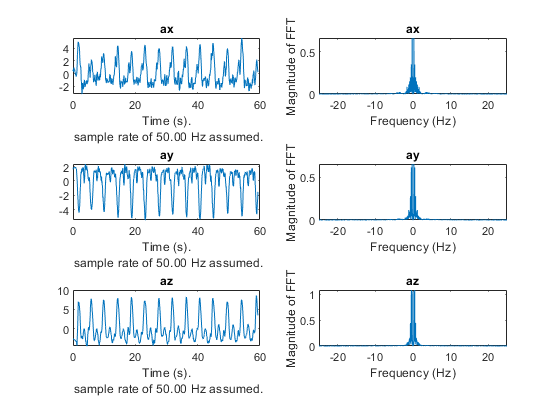

figure
hold on
subplot(3,2,1)

make_time_plot(ax, Fs, 'ax')
subplot(3,2,2)
make_freq_plot(ax, Fs, 'ax')

subplot(3,2,3)
make_time_plot(ay, Fs, 'ay')
subplot(3,2,4)
make_freq_plot(ay, Fs, 'ay')

subplot(3,2,5)
make_time_plot(az, Fs, 'az')
subplot(3,2,6)
make_freq_plot(az, Fs, 'az')

hold off

% variable that keeps track of flowchart conditions
axLessThan_0_5 = 0

axLessThan_0_5 = 0

ayLessThan_0_2 = 0

ayLessThan_0_2 = 0





[max_ax_i, max_ax] = max(ax)

max_ax_i = 5.6123

max_ax = 2708

[max_ay_i, max_ay] = max(ay)

max_ay_i = 2.3673

max_ay = 832

[max_az_i, max_az] = max(az)

max_az_i = 8.5778

max_az = 2945

if max_ax<0.5
    axLessThan_0_5 = 1
end
if max_ay < 0.2
    ayLessThan_0_2 = 1
end




trickname

Undefined function or variable 'inputArg2'.